# SNW_VFI_MAIN_BISEC_VEC Tiny Solution Analysis

This is the example vignette for function: [**snw_vfi_main_bisec_vec**](https://github.com/FanWangEcon/PrjOptiSNW/tree/master/PrjOptiSNW/svalpol/snw_vfi_main_bisec_vec.m) from the [**PrjOptiSNW Package**](https://fanwangecon.github.io/PrjOptiSNW/)**. **This function solves for policy function with vectorized bisection. Tiny Solution Analysis, husband 5 shocks, wife 1 shocks.

## Test SNW_VFI_MAIN_BISEC_VEC Defaults

Call the function with defaults.

mp_param = snw_mp_param('default_tiny');
[V_VFI,ap_VFI,cons_VFI,exitflag_VFI] = snw_vfi_main_bisec_vec(mp_param);

SNW_VFI_MAIN: Finished Age Group:7 of 7
SNW_VFI_MAIN: Finished Age Group:6 of 7
SNW_VFI_MAIN: Finished Age Group:5 of 7
SNW_VFI_MAIN: Finished Age Group:4 of 7
SNW_VFI_MAIN: Finished Age Group:3 of 7
SNW_VFI_MAIN: Finished Age Group:2 of 7
SNW_VFI_MAIN: Finished Age Group:1 of 7
Elapsed time is 0.167785 seconds.
Completed SNW_VFI_MAIN;SNW_MP_PARAM=;default_tiny;SNW_MP_CONTROL=;default_base


## Tiny Param Results Define Frames

Define the matrix dimensions names and dimension vector values. Policy and Value Functions share the same ND dimensional structure.

% Grids:
age_grid = [19, 28:16:92, 100];
agrid = mp_param('agrid')';
eta_H_grid = mp_param('eta_H_grid')';
eta_S_grid = mp_param('eta_S_grid')';
ar_st_eta_HS_grid = string(cellstr([num2str(eta_H_grid', 'hz=%3.2f;'), num2str(eta_S_grid', 'wz=%3.2f')]));
edu_grid = [0,1];
marry_grid = [0,1];
kids_grid = (1:1:mp_param('n_kidsgrid'))';
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
cl_mp_datasetdesc = {};
cl_mp_datasetdesc{1} = containers.Map({'name', 'labval'}, {'age', age_grid});
cl_mp_datasetdesc{2} = containers.Map({'name', 'labval'}, {'savings', agrid});
cl_mp_datasetdesc{3} = containers.Map({'name', 'labval'}, {'Hshock', eta_H_grid});
cl_mp_datasetdesc{4} = containers.Map({'name', 'labval'}, {'edu', edu_grid});
cl_mp_datasetdesc{5} = containers.Map({'name', 'labval'}, {'marry', marry_grid});
cl_mp_datasetdesc{6} = containers.Map({'name', 'labval'}, {'kids', kids_grid});

## Analyze Savings and Shocks

First, analyze Savings Levels and Shocks, Aggregate Over All Others, and do various other calculations.

% Generate some Data
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
mp_support_graph('cl_st_xtitle') = {'Savings States, a'};
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = true; % do not log

#### MEAN(VAL(A,Z)), MEAN(AP(A,Z)), MEAN(C(A,Z))

Tabulate value and policies along savings and shocks:

% Set
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [1,4,5,6,3,2];
% Value Function
tb_az_v = ff_summ_nd_array("MEAN(VAL(A,Z))", V_VFI, true, ["mean"], 4, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(VAL(A,Z))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    savings    mean_Hshock__0_72413    mean_Hshock__0_36206    mean_Hshock_0    mean_Hshock_0_36206    mean_Hshock_0_72413
    _____    _______    ____________________    ____________________    _____________    ___________________    ___________________

      1            0          -3.8889                 -3.1291              -2.5194             -2.0514                -1.6857      
      2      0.26063          -1.7646                 -1.4089              -1.0833            -0.79352               -0.52369      
      3        2.085          0.54364                  0.6007              0.66603             0.73766                 0.8127      
      4        7.037           1.2952               

% Aprime Choice
tb_az_ap = ff_summ_nd_array("MEAN(AP(A,Z))", ap_VFI, true, ["mean"], 4, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(AP(A,Z))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    savings    mean_Hshock__0_72413    mean_Hshock__0_36206    mean_Hshock_0    mean_Hshock_0_36206    mean_Hshock_0_72413
    _____    _______    ____________________    ____________________    _____________    ___________________    ___________________

      1            0         0.0065356                 0.0214             0.044317            0.073813                0.14659      
      2      0.26063           0.10777                0.12741               0.1382             0.17658                0.29115      
      3        2.085            1.3982                 1.4039               1.4039              1.4039                 1.4039      
      4        7.037             4.616               

% Consumption Choices
tb_az_c = ff_summ_nd_array("MEAN(C(A,Z))", cons_VFI, true, ["mean"], 4, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(C(A,Z))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    savings    mean_Hshock__0_72413    mean_Hshock__0_36206    mean_Hshock_0    mean_Hshock_0_36206    mean_Hshock_0_72413
    _____    _______    ____________________    ____________________    _____________    ___________________    ___________________

      1            0          0.50396                 0.58938              0.70762             0.87767                1.0881       
      2      0.26063          0.84284                 0.92213               1.0513              1.2115                1.3794       
      3        2.085           2.5899                  2.6802               2.8174              3.0132                3.2932       
      4        7.037           7.5525                 

Graph Mean Values:

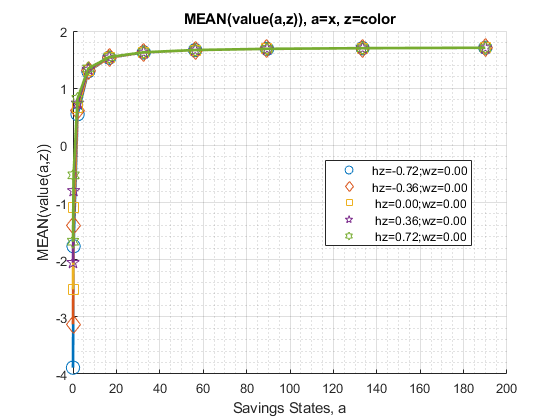

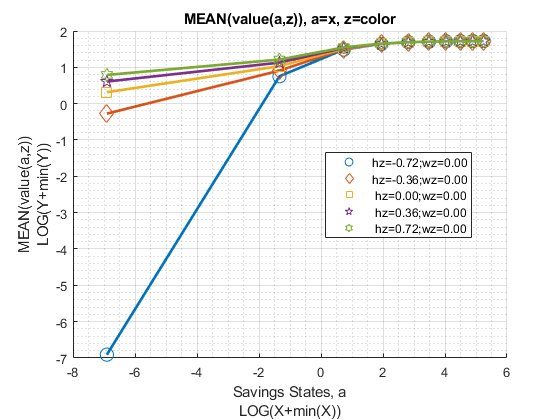

mp_support_graph('cl_st_graph_title') = {'MEAN(value(a,z)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'MEAN(value(a,z))'};
ff_graph_grid((tb_az_v{1:end, 3:end})', ar_st_eta_HS_grid, agrid, mp_support_graph);

Graph Mean Savings Choices:

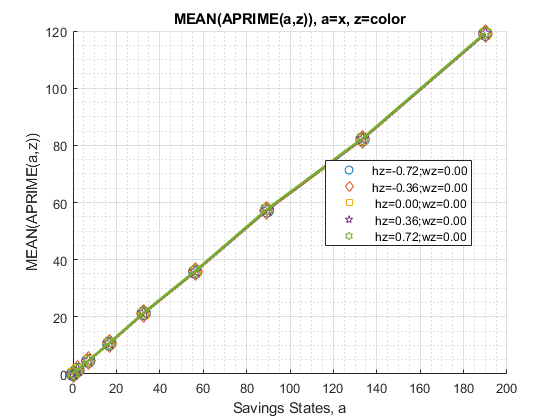

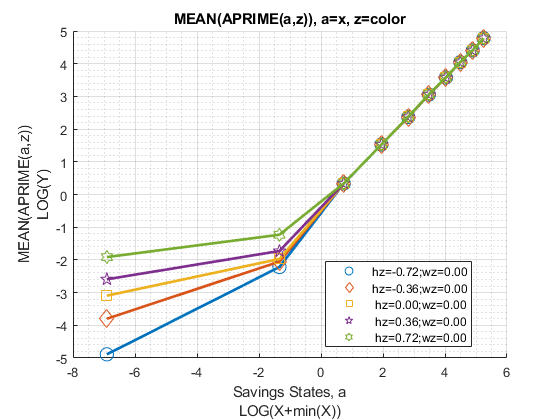

mp_support_graph('cl_st_graph_title') = {'MEAN(APRIME(a,z)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'MEAN(APRIME(a,z))'};
ff_graph_grid((tb_az_ap{1:end, 3:end})', ar_st_eta_HS_grid, agrid, mp_support_graph);

Graph Mean Consumption:

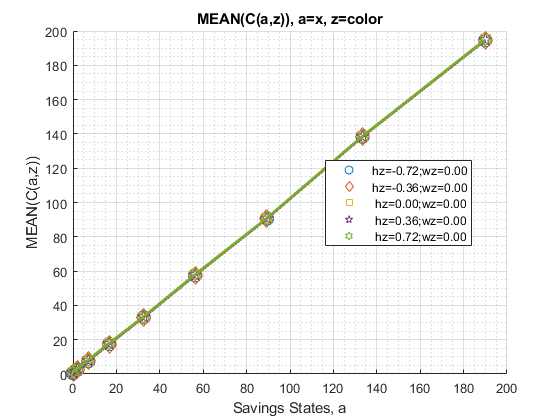

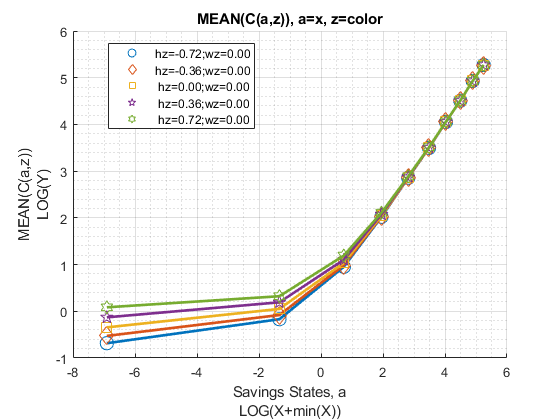

mp_support_graph('cl_st_graph_title') = {'MEAN(C(a,z)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'MEAN(C(a,z))'};
ff_graph_grid((tb_az_c{1:end, 3:end})', ar_st_eta_HS_grid, agrid, mp_support_graph);

## Analyze Kids and Marriage and Age

Aggregating over education, savings, and shocks, what are the differential effects of Marriage and Age.

% Generate some Data
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
ar_row_grid = ["k0M0", "K1M0", "K2M0", "k0M1", "K1M1", "K2M1"];
mp_support_graph('cl_st_xtitle') = {'Age'};
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = true; % do not log
mp_support_graph('st_rounding') = '6.2f'; % format shock legend
mp_support_graph('cl_scatter_shapes') = { 'o', 'd' ,'s', 'o', 'd', 's'};
mp_support_graph('cl_colors') = {'red', 'red', 'red', 'blue', 'blue', 'blue'};

#### MEAN(VAL(KM,J)), MEAN(AP(KM,J)), MEAN(C(KM,J))

Tabulate value and policies:

% Set
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [2,3,4,1,6,5];
% Value Function
tb_az_v = ff_summ_nd_array("MEAN(VAL(KM,J))", V_VFI, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(VAL(KM,J))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    kids    marry    mean_age_19    mean_age_28    mean_age_44    mean_age_60    mean_age_76    mean_age_92    mean_age_100
    _____    ____    _____    ___________    ___________    ___________    ___________    ___________    ___________    ____________

      1       1        0         1.5515        1.5391         1.3783          1.0427        0.38793          0.3806        0.38678  
      2       2        0         1.1866        1.2613         1.1507          0.8222       0.053186         0.12139        0.13278  
      3       3        0        0.95504        1.0414         0.9399         

% Aprime Choice
tb_az_ap = ff_summ_nd_array("MEAN(AP(KM,J))", ap_VFI, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(AP(KM,J))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    kids    marry    mean_age_19    mean_age_28    mean_age_44    mean_age_60    mean_age_76    mean_age_92    mean_age_100
    _____    ____    _____    ___________    ___________    ___________    ___________    ___________    ___________    ____________

      1       1        0        54.646          53.56         50.996         40.092          29.56         8.4444            0      
      2       2        0        54.447          53.14         49.191         37.735         27.337         8.4444            0      
      3       3        0        54.038         52.968          49.17         3

% Consumption Choices
tb_az_c = ff_summ_nd_array("MEAN(C(KM,J))", cons_VFI, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(C(KM,J))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    kids    marry    mean_age_19    mean_age_28    mean_age_44    mean_age_60    mean_age_76    mean_age_92    mean_age_100
    _____    ____    _____    ___________    ___________    ___________    ___________    ___________    ___________    ____________

      1       1        0        33.006          34.34          37.17         48.039         57.718         78.834          87.278   
      2       2        0        33.204          34.76         38.975         50.396         59.941         78.834          87.278   
      3       3        0        33.613         34.932         38.996         50

Graph Mean Values:

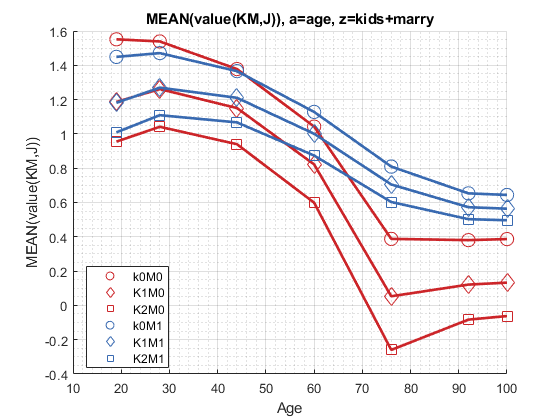

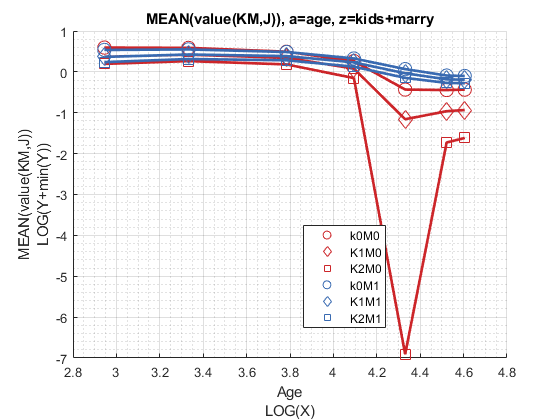

mp_support_graph('cl_st_graph_title') = {'MEAN(value(KM,J)), a=age, z=kids+marry'};
mp_support_graph('cl_st_ytitle') = {'MEAN(value(KM,J))'};
ff_graph_grid((tb_az_v{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

Graph Mean Savings Choices:

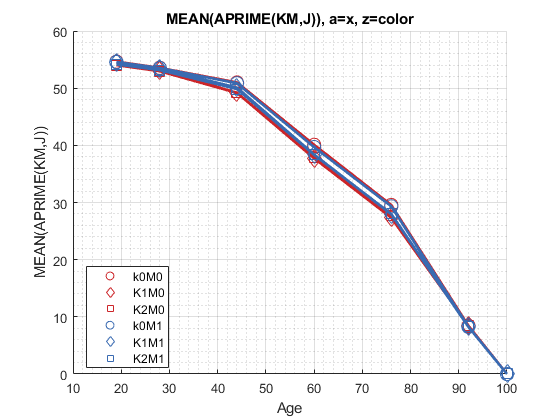

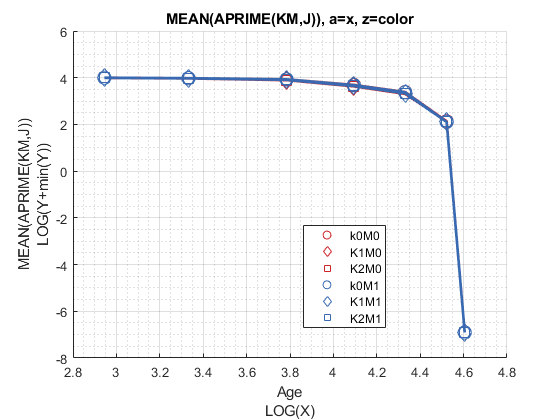

mp_support_graph('cl_st_graph_title') = {'MEAN(APRIME(KM,J)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'MEAN(APRIME(KM,J))'};
ff_graph_grid((tb_az_ap{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

Graph Mean Consumption:

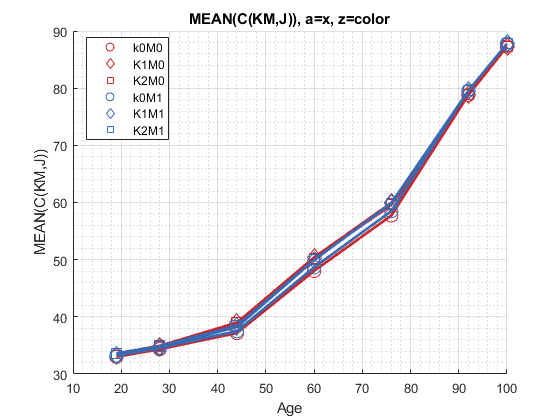

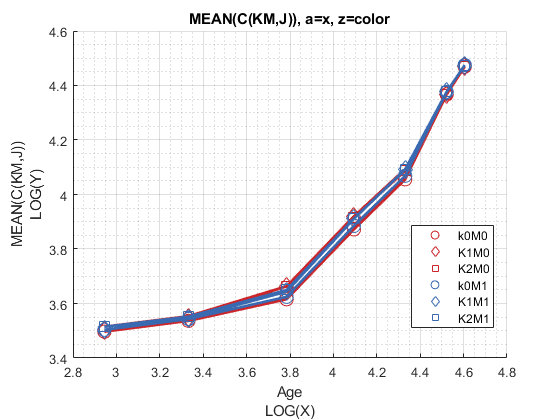

mp_support_graph('cl_st_graph_title') = {'MEAN(C(KM,J)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'MEAN(C(KM,J))'};
ff_graph_grid((tb_az_c{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

## Analyze Education and Marriage and Age

Aggregating over education, savings, and shocks, what are the differential effects of Marriage and Age.

% Generate some Data
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
ar_row_grid = ["E0M0", "E1M0", "E0M1", "E1M1"];
mp_support_graph('cl_st_xtitle') = {'Age'};
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = true; % do not log
mp_support_graph('st_rounding') = '6.2f'; % format shock legend
mp_support_graph('cl_scatter_shapes') = {'*', 'p', '*','p' };
mp_support_graph('cl_colors') = {'red', 'red', 'blue', 'blue'};

#### MEAN(VAL(EKM,J)), MEAN(AP(EKM,J)), MEAN(C(EKM,J))

Tabulate value and policies:

% Set
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [2,3,6,1,4,5];
% Value Function
tb_az_v = ff_summ_nd_array("MEAN(VAL(EKM,J))", V_VFI, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(VAL(EKM,J))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    edu    marry    mean_age_19    mean_age_28    mean_age_44    mean_age_60    mean_age_76    mean_age_92    mean_age_100
    _____    ___    _____    ___________    ___________    ___________    ___________    ___________    ___________    ____________

      1       0       0        1.1623         1.1801         1.0576         0.73303       -0.022293      0.082279        0.096964  
      2       1       0        1.2998         1.3811          1.255         0.90951          0.1433        0.1971           0.208  
      3       0       1        1.1338         1.1842         1.1256         0.93

% Aprime Choice
tb_az_ap = ff_summ_nd_array("MEAN(AP(EKM,J))", ap_VFI, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(AP(EKM,J))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    edu    marry    mean_age_19    mean_age_28    mean_age_44    mean_age_60    mean_age_76    mean_age_92    mean_age_100
    _____    ___    _____    ___________    ___________    ___________    ___________    ___________    ___________    ____________

      1       0       0        54.373         53.203         49.674         38.466         28.174         8.4444            0      
      2       1       0        54.381         53.241         49.897         38.707         28.234         8.4444            0      
      3       0       1        54.436         53.345         50.211         38.72

% Consumption Choices
tb_az_c = ff_summ_nd_array("MEAN(C(EKM,J))", cons_VFI, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(C(EKM,J))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    edu    marry    mean_age_19    mean_age_28    mean_age_44    mean_age_60    mean_age_76    mean_age_92    mean_age_100
    _____    ___    _____    ___________    ___________    ___________    ___________    ___________    ___________    ____________

      1       0       0        33.278         34.595         38.305         49.496         59.086         78.815           87.26   
      2       1       0         33.27         34.759         38.455         49.593         59.063         78.852          87.296   
      3       0       1        33.334         34.588         37.918         49.403

Graph Mean Values:

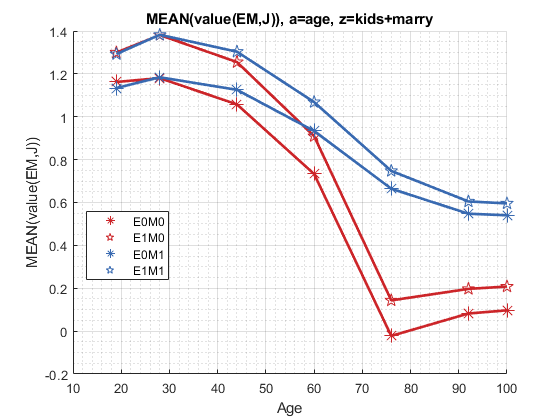

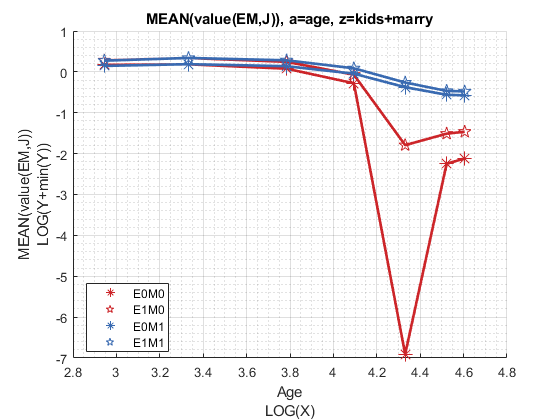

mp_support_graph('cl_st_graph_title') = {'MEAN(value(EM,J)), a=age, z=kids+marry'};
mp_support_graph('cl_st_ytitle') = {'MEAN(value(EM,J))'};
ff_graph_grid((tb_az_v{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

Graph Mean Savings Choices:

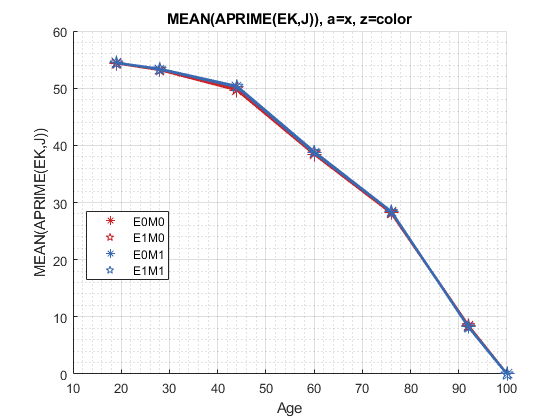

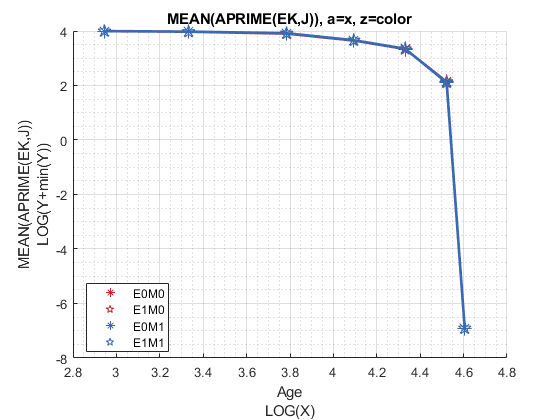

mp_support_graph('cl_st_graph_title') = {'MEAN(APRIME(EK,J)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'MEAN(APRIME(EK,J))'};
ff_graph_grid((tb_az_ap{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

Graph Mean Consumption:

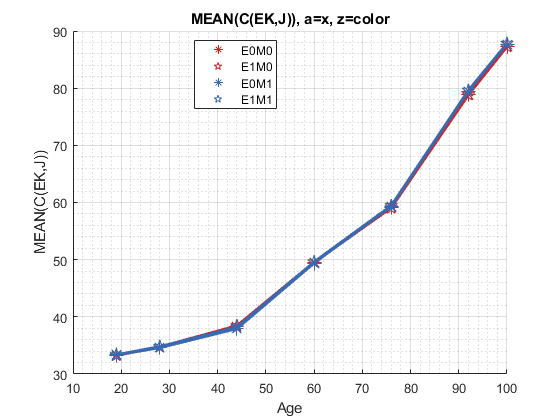

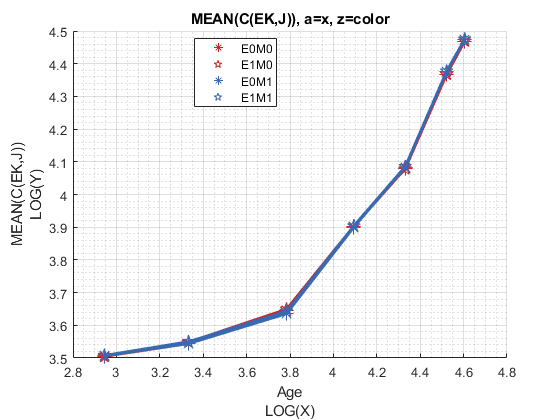

mp_support_graph('cl_st_graph_title') = {'MEAN(C(EK,J)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'MEAN(C(EK,J))'};
ff_graph_grid((tb_az_c{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);